# **Solving Ordinary Differential Equations**

## **1. Solving the Initial Value Problems**

### Example 1 $u^\prime=u^2$

syms u(t)
ode1=diff(u,t,1)-u^2;
d1 =0.8;
data1=u(0)==d1;
u1(t)=dsolve(ode1,data1)

$$u1(t) = -\frac{1}{t-\frac{5}{4}}$$

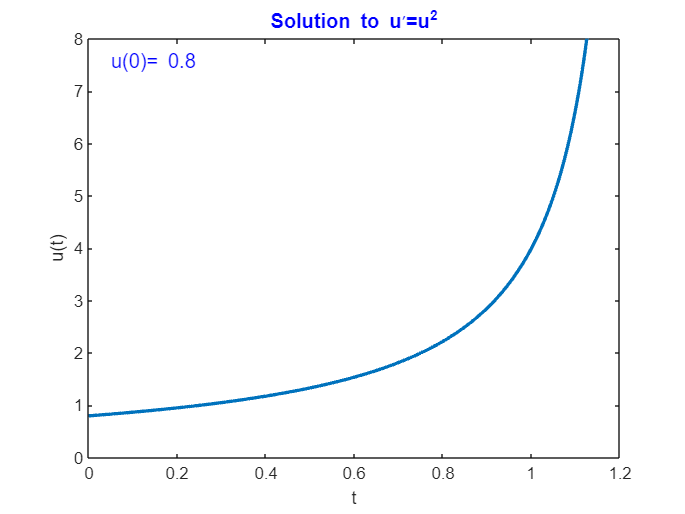

t=0:0.005:1/d1-0.01;
strd1=string(d1);
plot(t,u1(t),'LineWidth',2)
ylim([0,10*d1])
xlabel('t')
ylabel('u(t)')
text(1/25/d1,9.5*d1,'u(0)=','Color','blue','FontSize',12)
text(1/7/d1,9.5*d1,strd1,'Color','blue','FontSize',12)
title('Solution to u^\prime=u^2','Color','blue','FontSize',12)

### Example 2 $u^{\prime\prime}+\gamma u^\prime + k u = \sin(\omega t)$

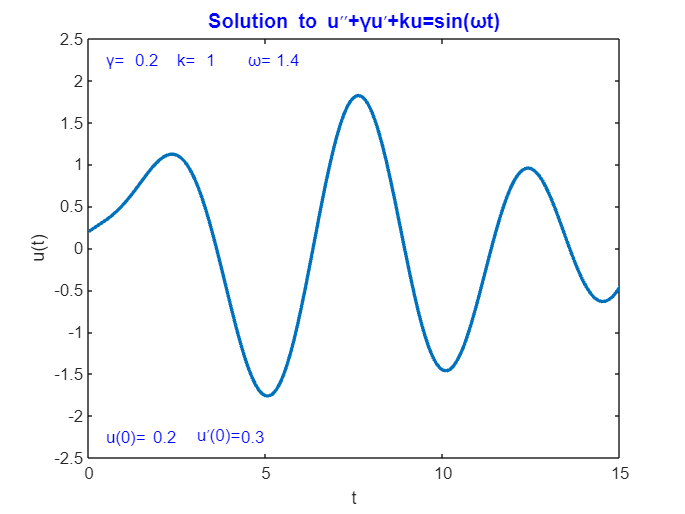

gamma =0.2; k = 1; 
omega = 1.4;
syms u(t)
Du=diff(u);
ode2=diff(u,t,2)+gamma*diff(u,t,1)+k*u-sin(omega*t);
d20 = 0.2; d21 = 0.3;
data20=u(0)==d20;
data21=Du(0)==d21;
data2=[data20 data21];
u2(t)=dsolve(ode2,data2);
t=0:0.1:15;
strg=string(gamma);
strk=string(k);
stromg=string(omega);
strd20=string(d20);
strd21=string(d21);
plot(t,u2(t),'LineWidth',2)
ylim([-5*d20-5*d21,5*d20+5*d21])
xlabel('t')
ylabel('u(t)')
text(0.5,4.5*d20+4.5*d21,'γ=','Color','blue','FontSize',10)
text(1.3,4.5*d20+4.5*d21,strg,'Color','blue','FontSize',10)
text(2.5,4.5*d20+4.5*d21,'k=','Color','blue','FontSize',10)
text(3.3,4.5*d20+4.5*d21,strk,'Color','blue','FontSize',10)
text(4.5,4.5*d20+4.5*d21,'ω=','Color','blue','FontSize',10)
text(5.3,4.5*d20+4.5*d21,stromg,'Color','blue','FontSize',10)
text(0.5,-4.5*d20-4.5*d21,'u(0)=','Color','blue','FontSize',10)
text(1.8,-4.5*d20-4.5*d21,strd20,'Color','blue','FontSize',10)
text(3,-4.5*d20-4.5*d21,'u^\prime(0)=','Color','blue','FontSize',10)
text(4.3,-4.5*d20-4.5*d21,strd21,'Color','blue','FontSize',10)
title('Solution to u^{\prime\prime}+γu^\prime+ku=sin(ωt)','Color','blue','FontSize',12)